# **电子信息工程建模与仿真作业二**

**姓名：李锦川   班级：119070201   学号：11907980422**

**一、如图所示机械系统， 设质量 M=20kg, 摩擦系数 B =50N/m/sec, 弹簧常数 K=250N/m。在 t=0 时刻，施 加 1000N 的拉力。请对系统进行仿真，并画出位移 及速度 的响应曲线。**

 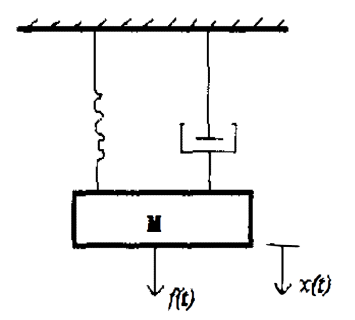

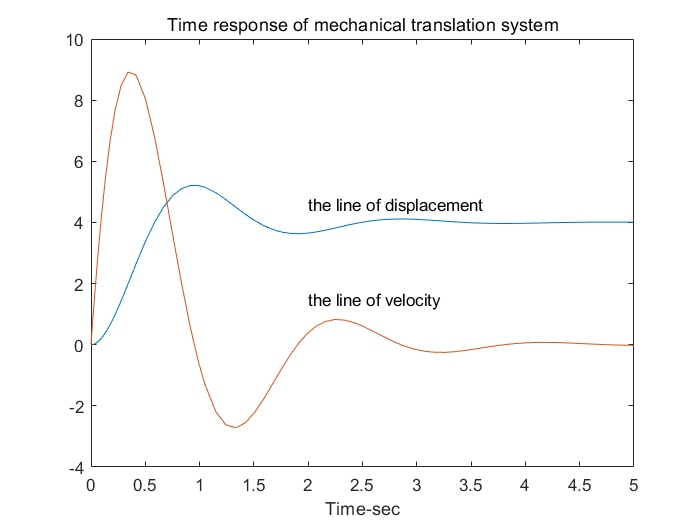

t0=0; %分析时间的起始地址
tfinal=5; %分析时间的终止地址
x0=[0 0];
tol=0.001;
trace=0;
[t,x]=ode23(@mechsys,[t0 tfinal],x0);
plot(t,x)
title('Time response of mechanical translation system')
xlabel('Time-sec')
text(2,4.6,'the line of displacement');
text(2,1.5,'the line of velocity');

**二、 把下列传递函数函数模型转换为零极点模型：**


$$H\left(s\right)=\frac{s^3 +9s^2 +26s+24}{s^3 +18s^2 +107s+210}$$


num=[1 9 26 24]; %分子系数

脚本中的函数定义必须出现在文件的结尾。
请将 "mechsys" 函数定义后面的所有语句都移到第一个局部函数定义前面。

den=[1 18 107 210]; %分母系数
[z,p,k]=tf2zp(num,den)

z =    -4.0000
   -3.0000
   -2.0000


p =    -7.0000
   -6.0000
   -5.0000


k = 1

由[z,p,k]的结果可知，系统传递函数的零极点模型为：


$$H\left(s\right)=\frac{\left.\textrm{（s}+4\right)\left(s+3\right)\left(s+2\right)}{\left(s+7\right)\left(s+6\right)\left(s+5\right)}$$


**三、对 H(s)进行部分分式展开： **


$$F\left(s\right)=\frac{s^2 +5s+6}{s^3 +18s^2 +107s+210}$$


b=[1 5 6];
a=[1 18 107 210];
[z,p,k]=residue(b,a)

z =    10.0000
  -12.0000
    3.0000


p =    -7.0000
   -6.0000
   -5.0000



k =

     []



由[z,p,k]的结果可知，F(s)部分分式展开为：


$$F\left(s\right)=\frac{3}{s+5}-\frac{12}{s+6}+\frac{10}{s+7}$$


function xdot=mechsys(t,x)
F=1000;   %施加力
M=20;    %质量
B=50;    %摩擦系数
K=250;   %弹簧常数
xdot=[x(2);1/M*(F-B*x(2)-K*x(1))];
end